# Proyecto 1 de Algoritmos Numéricos

#### Anairam Mar 181375, Sebastián González 174145, Lucia Renata Moreno 187541

## Introducción.

La derivada respecto a x de una función y = f(x) es una medida del cambio del valor *y *con respecto al cambio de la variable *x*. Hay múltiples maneras de calcularla. Una de ellas es el método de diferenciación numérica, que calcula los valores de la derivada de *f *con base en valores dados de f(x) y que se usa en el cálculo de ecuaciones diferenciales. Los tres métodos de diferenciación numérica más comunes son los de diferenciación hacia atrás, diferenciación hacia adelante y diferenciación centrada, llamados así por los valores iniciales que toman. Sus fórmulas respectivas para la primera derivada son las siguientes:

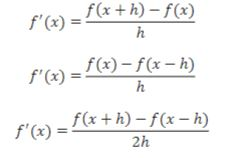

Estos métodos también se conocen como diferencias finitas, un nombre dado porque comparan diferentes puntos. Las definiciones de los métodos se basan en las expansiones para adelante y para atrás de la serie de Taylor, y la “h” se suma y resta para usar los vecinos más próximos a “x”, el valor inicial.

Otra manera de calcular la diferenciación numérica hacia adelante, hacia atrás y centrada es usando el “método de coeficientes”. Este utiliza más términos de la serie de Taylor.  

Los resultados de estos seis métodos son una aproximación del valor real de la derivada de *f*. Esto es porque los cocientes suelen tener cantidades grandes como numeradores que se dividen entre denominadores pequeños. Esto ocasiona errores de redondeo en las sumas y restas así como inestabilidad en las divisiones. 

Entonces, los resultados de los métodos de diferenciación numérica están alejados de los valores reales de la derivada por una distancia que se llama “error de truncación”. Este se categoriza utilizando notación Big O. El error de las fórmulas de primera derivada hacia delante y hacia atrás usando el método de diferencias finitas es de orden O(h); es un orden más bajo que O(h^2), que es el valor que tiene la derivada central usando el método de diferencias finitas. Los errores respectivos para el método de coeficientes dependen de cuántos términos de la serie de Taylor se incorporen. Incorporamos un órden de precisión 2, entonces nuestras fórmulas para el método de coeficientes de diferenciación hacia adelante, hacia atrás y centrada tenían errores de O(h^2), O(h^2) y O(h^4). 

Obtuvimos el error de truncación de cada método al comparar su resultado con el real de la derivada de la función dada. Analizamos doce fórmulas en total: había primeras y segundas derivadas y tres tipos de cálculos de diferenciación (hacia adelante, hacia atrás, central), cada uno con dos formas de hacerse (diferencias finitas o coeficientes). Graficamos cada una. Como los valores de h influyen en los errores de redondeo e inestabilidad, probamos la exactitud con diferentes valores de h. La dividimos entre diez once veces y comparamos la exactitud de las fórmulas para cada valor de h.

Utilizamos loglog en las gráficas para poder ver la variación entre los errores, cosa que habría sido imposible con un plano con ejes de valores no-logarítmicos ya que los valores cambiaban de forma exponencial. La fórmula con el menor error de truncamiento sería la más exacta y conveniente de utilizar. 

Usamos la misma función para probar todos los métodos. 

Esta fue f(x) = 0.67*x.^4-1.15*x.^3-2*x.^2-0.45*x+1.2. 

## Resultados

ff=@(x) 0.67*x.^4-1.15*x.^3-2*x.^2-0.45*x+1.2;
x1 = 0.5; 

### Fórmulas de diferencias finitas 

#### Primera derivada

Diferencias finitas hacia adelante

[E, H, D] =forwardfirstder(x1, ff);
L=[H' D' E']';
fprintf(' Error verdadero en diferencias finitas hacia adelante\n');

 Error verdadero en diferencias finitas hacia adelante


fprintf('Step size    Derivada en el punto    Error\n');

Step size    Derivada en el punto    Error


fprintf('%14.10f %16.14f %16.13f\n',L);

  1.0000000000 -4.83750000000000  1.8600000000000
  0.1000000000 -3.24693000000000  0.2694300000000
  0.0100000000 -3.00468033000001  0.0271803300000
  0.0010000000 -2.98021980933005  0.0027198093301
  0.0001000000 -2.97777199809945  0.0002719980995
  0.0000100000 -2.97752719998767  0.0000271999877
  0.0000010000 -2.97750272004738  0.0000027200474
  0.0000001000 -2.97750027189458  0.0000002718946
  0.0000000100 -2.97750004651931  0.0000000465193
  0.0000000010 -2.97750002431485  0.0000000243148
  0.0000000001 -2.97750046840406  0.0000004684041
  0.0000000000 -2.97750712974221  0.0000071297422
  0.0000000000 -2.97750712974221  0.0000071297422
  0.0000000000 -2.97983859809392  0.0023385980939
  0.0000000000 -2.98649993624167  0.0089999362417


loglog(H,E),xlabel('Variaciones en h'),ylabel('Error')
title('Error verdadero contra tamaño de paso')
hold on
format short

Diferencias finitas hacia atrás

[E, H, D] =backwardfirstder(x1, ff);
L=[H' D' E']';
fprintf(' Error verdadero en diferencias finitas hacia atrás\n');

 Error verdadero en diferencias finitas hacia atrás


fprintf('%14.10f %16.14f %16.13f\n',L);

  1.0000000000 -0.73750000000000  2.2400000000000
  0.1000000000 -2.70427000000000  0.2732300000000
  0.0100000000 -2.95028167000000  0.0272183300000
  0.0010000000 -2.97477981066996  0.0027201893300
  0.0001000000 -2.97722799809996  0.0002720019000
  0.0000100000 -2.97747279996985  0.0000272000302
  0.0000010000 -2.97749727984353  0.0000027201565
  0.0000001000 -2.97749972677508  0.0000002732249
  0.0000000100 -2.97749996880370  0.0000000311963
  0.0000000010 -2.97749991329255  0.0000000867075
  0.0000000001 -2.97749935818103  0.0000006418190
  0.0000000000 -2.97748492528171  0.0000150747183
  0.0000000000 -2.97739610743974  0.0001038925603
  0.0000000000 -2.97650792902004  0.0009920709800
  0.0000000000 -2.96429547574917  0.0132045242508


loglog(H,E)
title('Error verdadero contra tamaño de paso')
format short

Diferencias finitas centradas

[E, H, D] =centeredfirstder(x1, ff);
L=[H' D' E']';
fprintf(' Error verdadero en diferencias finitas centradas\n');

 Error verdadero en diferencias finitas centradas


fprintf('%14.10f %16.14f %16.13f\n',L);

  1.0000000000 -2.78750000000000  0.1900000000000
  0.1000000000 -2.97560000000000  0.0019000000000
  0.0100000000 -2.97748100000000  0.0000190000000
  0.0010000000 -2.97749981000001  0.0000001900000
  0.0001000000 -2.97749999809971  0.0000000019003
  0.0000100000 -2.97749999997876  0.0000000000212
  0.0000010000 -2.97749999994545  0.0000000000545
  0.0000001000 -2.97749999933483  0.0000000006652
  0.0000000100 -2.97750000766150  0.0000000076615
  0.0000000010 -2.97749996880370  0.0000000311963
  0.0000000001 -2.97749991329255  0.0000000867075
  0.0000000000 -2.97749602751196  0.0000039724880
  0.0000000000 -2.97745161859098  0.0000483814090
  0.0000000000 -2.97817326355698  0.0006732635570
  0.0000000000 -2.97539770599542  0.0021022940046


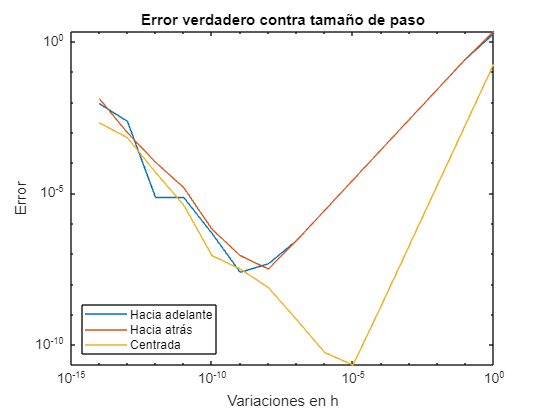

loglog(H,E)
title('Error verdadero contra tamaño de paso')
format short
legend('Hacia adelante', 'Hacia atrás', 'Centrada');
legend('Location','southwest');
hold off

#### Segunda derivada

Diferencias finitas hacia adelante

[E, H, D] =forwardsecder(x1, ff);
L=[H' D' E']';
fprintf(' Error verdadero en diferencias finitas hacia adelante\n');

 Error verdadero en diferencias finitas hacia adelante


fprintf('%14.10f %16.14f %16.13f\n',L);

  1.0000000000 5.08000000000000 10.5200000000000
  0.1000000000 -5.23220000000000  0.2078000000000
  0.0100000000 -5.42766199999933  0.0123380000007
  0.0010000000 -5.43885061998761  0.0011493800124
  0.0001000000 -5.43988590839817  0.0001140916018
  0.0000100000 -5.43998845969895  0.0000115403010
  0.0000010000 -5.43987077605834  0.0001292239417
  0.0000001000 -5.45119505090952  0.0111950509095
  0.0000000100 -1.11022302462516  4.3297769753748
  0.0000000010 -222.04460492503128 216.6046049250313
  0.0000000001 0.00000000000000  5.4400000000000
  0.0000000000 1110223.02462515630759 1110228.4646251562517
  0.0000000000 111022302.46251566708088 111022307.9025156646967
  0.0000000000 55511151231.25782775878906 55511151236.6978302001953
  0.0000000000 2220446049250.31298828125000 2220446049255.7529296875000


loglog(H,E),xlabel('Variaciones en h'),ylabel('Error')
title('Error verdadero contra tamaño de paso ')
hold on
format short

Diferencias finitas hacia atrás

[E, H, D] =backwardsecder(x1, ff);
L=[H' D' E']';
fprintf(' Error verdadero en diferencias finitas hacia atrás\n');

 Error verdadero en diferencias finitas hacia atrás


fprintf('%14.10f %16.14f %16.13f\n',L);

  1.0000000000 2.80000000000000  8.2400000000000
  0.1000000000 -5.46020000000000  0.0202000000000
  0.0100000000 -5.45046199999955  0.0104619999995
  0.0010000000 -5.44113061995422  0.0011306199542
  0.0001000000 -5.44011391490073  0.0001139149007
  0.0000100000 -5.44000955393642  0.0000095539364
  0.0000010000 -5.43975975375588  0.0002402462441
  0.0000001000 -5.41788836017076  0.0221116398292
  0.0000000100 -5.55111512312578  0.1111151231258
  0.0000000010 111.02230246251564 116.4623024625156
  0.0000000001 11102.23024625156359 11107.6702462515641
  0.0000000000 3330669.07387546915561 3330674.5138754690997
  0.0000000000 111022302.46251566708088 111022307.9025156646967
  0.0000000000 11102230246.25156402587891 11102230251.6915645599365
  0.0000000000 1110223024625.15649414062500 1110223024630.5964355468750


loglog(H,E)
title('Error verdadero contra tamaño de paso ')
format short

Diferencias finitas hacia centradas

[E, H, D] =centeredsecder(x1, ff);
L=[H' D' E']';
fprintf(' Error verdadero en diferencias finitas centradas\n');

 Error verdadero en diferencias finitas centradas


fprintf('%14.10f %16.14f %16.13f\n',L);

  1.0000000000 -4.10000000000000  1.3400000000000
  0.1000000000 -5.42660000000000  0.0134000000000
  0.0100000000 -5.43986600000101  0.0001339999990
  0.0010000000 -5.43999866009504  0.0000013399050
  0.0001000000 -5.43999999491618  0.0000000050838
  0.0000100000 -5.44000178237525  0.0000017823752
  0.0000010000 -5.44020384296573  0.0002038429657
  0.0000001000 -5.45119505090952  0.0111950509095
  0.0000000100 -7.77156117237609  2.3315611723761
  0.0000000010 -111.02230246251564 105.5823024625156
  0.0000000001 -11102.23024625156359 11096.7902462515631
  0.0000000000 -2220446.04925031261519 2220440.6092503126711
  0.0000000000 -111022302.46251566708088 111022297.0225156694651
  0.0000000000 -33306690738.75469589233398 33306690733.3146972656250
  0.0000000000 -2220446049250.31298828125000 2220446049244.8730468750000


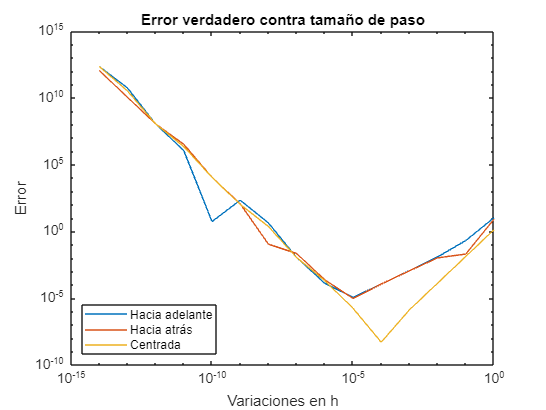

loglog(H,E)
title('Error verdadero contra tamaño de paso')
legend('Hacia adelante', 'Hacia atrás', 'Centrada');
legend('Location','southwest');
hold off

format short

### Método de coeficientes de diferencias finitas 

#### Primera derivada

Método de coeficientes hacia adelante

[E, H, D] =m2forwardfirstder(x1, ff);
L=[H' D' E']';
fprintf(' Error verdadero en diferencias de coeficientes hacia adelante\n');

 Error verdadero en diferencias de coeficientes hacia adelante


fprintf('%14.10f %16.14f %16.13f\n',L);

  1.0000000000 -2.97750000000000  4.4000000000000
  0.1000000000 -2.97750000000000  0.0078200000000
  0.0100000000 -2.97750000000000  0.0000420200000
  0.0010000000 -2.97750000000000  0.0000003840201
  0.0001000000 -2.97750000000000  0.0000000038046
  0.0000100000 -2.97750000000000  0.0000000000509
  0.0000010000 -2.97750000000000  0.0000000001675
  0.0000001000 -2.97749999977989  0.0000000001101
  0.0000000100 -2.97750000000000  0.0000000465193
  0.0000000010 -2.97749993760740  0.0000000311963
  0.0000000001 -2.97750000000000  0.0000010235156
  0.0000000000 -2.97750000000000  0.0000182319725
  0.0000000000 -2.97750000000000  0.0001181520447
  0.0000000000 -2.97750000000000  0.0056692671678
  0.0000000000 -2.97750000000000  0.0256532816110


loglog(H,E),xlabel('Variaciones en h'),ylabel('Error')
title('Error verdadero contra tamaño de paso')
hold on
format short

Método de coeficientes hacia atrás

[E, H, D] =m2backwardfirstder(x1, ff);
L=[H' D' E']';
fprintf(' Error verdadero en diferencias de coeficientes hacia atrás\n');

 Error verdadero en diferencias de coeficientes hacia atrás


fprintf('%14.10f %16.14f %16.13f\n',L);

  1.0000000000 4.30250000000000  3.6400000000000
  0.1000000000 -2.97706000000000  0.0002200000000
  0.0100000000 -2.97750000000000  0.0000339800000
  0.0010000000 -2.97750000000000  0.0000003759799
  0.0001000000 -2.97750000000000  0.0000000037952
  0.0000100000 -2.97750000000000  0.0000000000121
  0.0000010000 -2.97749999933580  0.0000000003321
  0.0000001000 -2.97749999422877  0.0000000028856
  0.0000000100 -2.97749998201632  0.0000000089918
  0.0000000010 -2.97749960454049  0.0000001977298
  0.0000000001 -2.97749649591602  0.0000017520420
  0.0000000000 -2.97742544164244  0.0000372791788
  0.0000000000 -2.97707017027456  0.0002149148627
  0.0000000000 -2.97329541199084  0.0021022940046
  0.0000000000 -2.92888649100583  0.0243067544971


loglog(H,E)
title('Error verdadero contra tamaño de paso')
format short

Método de coeficientes centradas

[E, H, D] =m2centralfirstder(x1, ff);
L=[H' D' E']';
fprintf(' Error verdadero en diferencias de coeficientes centradas\n');

 Error verdadero en diferencias de coeficientes centradas


fprintf('%14.10f %16.14f %16.13f\n',L);

  1.0000000000 -2.59750000000000  0.1900000000000
  0.1000000000 -2.97370000000000  0.0019000000000
  0.0100000000 -2.97746200000001  0.0000190000000
  0.0010000000 -2.97749962000001  0.0000001900000
  0.0001000000 -2.97749999619942  0.0000000019003
  0.0000100000 -2.97749999995752  0.0000000000212
  0.0000010000 -2.97749999989091  0.0000000000545
  0.0000001000 -2.97749999866966  0.0000000006652
  0.0000000100 -2.97750000000000  0.0000000076615
  0.0000000010 -2.97749993760740  0.0000000311963
  0.0000000001 -2.97749982658509  0.0000000867075
  0.0000000000 -2.97749205502392  0.0000039724880
  0.0000000000 -2.97740323718195  0.0000483814090
  0.0000000000 -2.97750000000000  0.0006732635570
  0.0000000000 -2.97329541199084  0.0021022940046


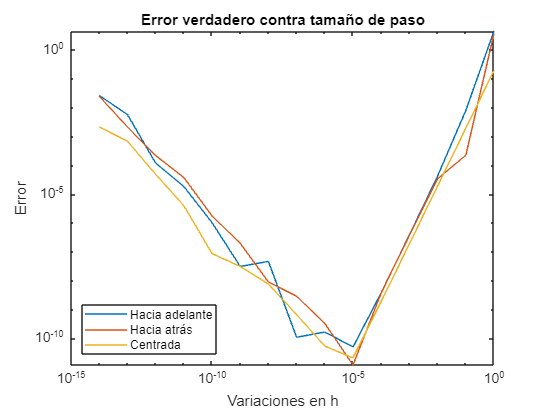

loglog(H,E)
title('Error verdadero contra tamaño de paso')
legend('Hacia adelante', 'Hacia atrás', 'Centrada');
legend('Location','southwest');
hold off

format short

#### Segunda derivada

Método de coeficientes hacia adelante

[E, H, D] =secforwardder(x1, ff);
L=[H' D' E']';
fprintf(' Error verdadero en diferencias de coeficientes hacia adelante\n');

 Error verdadero en diferencias de coeficientes hacia adelante


fprintf('%14.10f %16.14f %16.13f\n',L);

  1.0000000000 -20.18000000000000 14.7400000000000
  0.1000000000 -5.58740000000000  0.1474000000000
  0.0100000000 -5.44147399999861  0.0014739999986
  0.0010000000 -5.44001474023226  0.0000147402323
  0.0001000000 -5.44000016144963  0.0000001614496
  0.0000100000 -5.44000178237525  0.0000017823752
  0.0000010000 -5.43953770915095  0.0004622908490
  0.0000001000 -5.48450174164827  0.0445017416483
  0.0000000100 6.66133814775094 12.1013381477509
  0.0000000010 -777.15611723760958 771.7161172376095


loglog(H,E),xlabel('Variaciones en h'),ylabel('Error')
title('Error verdadero contra tamaño de paso')
hold on
format short

Método de coeficientes hacia atrás

[E, H, D] =secbackwardder(x1, ff);
L=[H' D' E']';
fprintf(' Error verdadero en diferencias de coeficientes hacia atrás\n');

 Error verdadero en diferencias de coeficientes hacia atrás


fprintf('%14.10f %16.14f %16.13f\n',L);

  1.0000000000 -20.18000000000000 14.7400000000000
  0.1000000000 -5.58740000000000  0.1474000000000
  0.0100000000 -5.44147399999639  0.0014739999964
  0.0010000000 -5.44001473978817  0.0000147397882
  0.0001000000 -5.44000019475632  0.0000001947563
  0.0000100000 -5.43999512103710  0.0000048789629
  0.0000010000 -5.43920464224357  0.0007953577564
  0.0000001000 -5.36237720893951  0.0776227910605
  0.0000000100 -6.66133814775094  1.2213381477509
  0.0000000010 222.04460492503128 227.4846049250313


loglog(H,E)
title('Error verdadero contra tamaño de paso')
format short

Método de coeficientes centradas

[E, H, D] =seccentralder(x1, ff);
L=[H' D' E']';
fprintf(' Error verdadero en diferencias de coeficientes centradas\n');

 Error verdadero en diferencias de coeficientes centradas


fprintf('%14.10f %16.14f %16.13f\n',L);

  1.0000000000 -4.10000000000000  1.3400000000000
  0.1000000000 -5.42660000000000  0.0134000000000
  0.0100000000 -5.43986600000101  0.0001339999990
  0.0010000000 -5.43999866009504  0.0000013399050
  0.0001000000 -5.43999999491618  0.0000000050838
  0.0000100000 -5.44000178237525  0.0000017823752
  0.0000010000 -5.44020384296573  0.0002038429657
  0.0000001000 -5.45119505090952  0.0111950509095
  0.0000000100 -7.77156117237609  2.3315611723761
  0.0000000010 -111.02230246251564 105.5823024625156


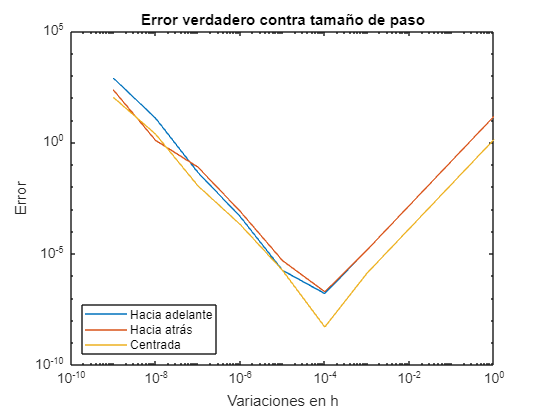

loglog(H,E)
title('Error verdadero contra tamaño de paso')
legend('Hacia adelante', 'Hacia atrás', 'Centrada');
legend('Location','southwest');
hold off

format short

## ¿Qué fórmulas presentan menos errores?

Al ver la comparación de los diferentes métodos en las gráficas, se puede notar que las diferencias centradas son las que presentan un error menor de forma general. Esto ocurre para las primeras y segundas derivadas del método de diferencias finitas y para las segundas derivadas del método de coeficientes. La fórmula más exacta para las primeras derivadas utilizando el método de coeficientes es la de derivación hacia atrás.

El método de coeficientes presentó una exactitud mayor al de diferencias finitas. Como se mencionó anteriormente, el método de diferencias finitas suele ser menos exacto dado a su simplicidad. El método de coeficientes incluye más información y esto resultó en cifras más exactas.

El método que tuvo menor error general fue el método de coeficientes de diferencias finitas centradas para la primera derivada. El punto mínimo de la gráfica, en el que el método mostró mayor exactitud, mostró un error de 10^-11. Esto es consistente con el orden de error conocido anteriormente. En este método es de O(h^2), mientras que en el resto es de O(h). 

## ¿Cómo dependen de h?

Las gráficas y los números muestran que el error de las funciones disminuyó a media que h se hizo más pequeño hasta llegar a un punto de mayor exactitud, que es el punto mínimo de la gráfica. Ahí se maximiza la precisión de la función. Después de esto, el error comenzó a crecer de nuevo. Entonces, hay una relación entre el tamaño del error y el tamaño de h. 

## ¿El error siempre disminuye si h se hace más pequeño? 

No. La forma en "V" de las gráficas muestra que, siguiendo el decrecimiento de h, el error baja hasta llegar a un mínimo y después vuelve a subir. Esto suele suceder alrededor de h = 10^-5. Sin embargo, hay un par de excepciones donde el mínimo ocurre en 10^-8 y hasta en 10^-11. 

## ¿Qué otro factor influye en el error? 

Los métodos de cálculo también influyen en el error. Los métodos de coeficientes arrojaron errores menores que los métodos de diferencias finitas. Debido a que Matlab hace un redondeo, hay cifras que se pierden y disminuye la exactitud. Por otra parte, el error humano puede generar errores al calcular las fórmulas. 

## Conclusiones

Los resultados nos mostraron que la aproximación mediante diferenciación finita centrada es la más exacta dentro de los métodos analizados ya que es la que muestra menor error (10^-11). Esto tiene sentido pues es de orden O(h^2). En dado caso de requerir un método de diferenciación numérica, el que recomendaríamos utilizar sería el de diferenciación finita centrada. Sus resultados siguen siendo aproximaciones y los errores de redondeo se exacerban utilizando Matlab, ya que puede no tomar en cuenta cifras que sean significativas, por lo que sería más recomendable utilizar integraciones o programas orientados al cálculo de derivadas para tratar de bajar el error lo más posible.

También observamos que hubo un patrón en todos los métodos donde el error disminuyó mientras h disminuía. Esto sucedió hasta llegar a un punto mínimo después del que el error comenzó a subir mientras la “h” siguió bajando. El patrón tiene que ver con el cociente, ya que el error va bajando a medida que los valores del nominador y denominador se aproximan y luego sube cuando se desacoplan una vez más.

## Bibliografía

Yew, A. (2011) Numerical differentiation: finite differences. Universidad de Brown. Recuperado el 23/02/2022 de [https://www.dam.brown.edu/people/alcyew/handouts/numdiff.pdf](https://www.dam.brown.edu/people/alcyew/handouts/numdiff.pdf) 

# Funciones

function [E, h, D] = forwardfirstder(x1,f)
format long
syms x g(x)
g(x)=f;
i = 1:1:15;
h= 10.^(1-i);
df = diff(g, 1);
df1 = df(x1); 
D=((f(x1+h)-f(x1))./h);
E=abs(df1-D);
end

function [E, h, D] = backwardfirstder(y,f)
format long
syms x g(x)
g(x)=f;
i = 1:1:15;
h= 10.^(1-i); 
df = diff(g, 1);
df1 = df(y); 
D=((f(y)-f(y-h))./h);
E=abs(df1-D);
end

function [E, h, D] = centeredfirstder(y,f)
format long
syms x g(x)
g(x)=f;
i = 1:1:15;
h= 10.^(1-i); 
df = diff(g, 1);
df1 = df(y); 
D=((f(y+h)-f(y-h))./(2*h));
E=abs(df1-D);
end

function [E, h, D] = backwardsecder(x1,f)
format long
syms x g(x)
g(x)=f;
i = 1:1:15;
h= 10.^(1-i);
df = diff(g, 2);
df1 = df(x1);
D=((f(x1)-2*f(x1-h)+f(x1-2*h))./(h.^2));
E=abs(df1-D);
end

function [E, h, D] = centeredsecder(y,f)
format long
syms x g(x)
g(x)=f;
i = 1:1:15;
h= 10.^(1-i);
df = diff(g, 2);
df1 = df(y);
D=((f(y+h)-2*f(y)+f(y-h))./(h.^2));
E=abs(df1-D);
end

function [E, h, D] = forwardsecder(x1,f)
format long
syms x g(x)
g(x)=f;
i = 1:1:15;
h= 10.^(1-i);
df = diff(g, 2);
df1 = df(x1);
D=((f(x1+2*h)-2*f(x1+h)+f(x1))./(h.^2));
E=abs(df1-D);
end

function [E, h, D] = m2backwardfirstder(x1, f)
format long
syms x g(x)
g(x) = f;
i = 1:1:15;
h= 10.^(1-i);
df = diff(g, 1);
df1 = df(x1);
D=((1.5*f(x1) - 2*f(x1-h) +0.5*f(x1-2.*h))./h);
E=abs(df1-D);
D=((1.5*f(x1) - 2*f(x1-h)+ 0.5*f(x1-2.*h))./h) + E;
end

function [E, h, D] = m2centralfirstder(x1, f)
format long
syms x g(x)
g(x) = f;
i = 1:1:15;
h= 10.^(1-i);
df = diff(g, 1);
df1 = df(x1);
D=((-0.5*f(x1-h)+0.5*f(x1+h))./h);
E=abs(df1-D);
D=((-0.5*f(x1-h)+0.5*f(x1+h))./h) + E;
end

function [E, h, D] = m2forwardfirstder(x1, f)
format long
syms x g(x)
g(x) = f;
i = 1:1:15;
h= 10.^(1-i);
df = diff(g, 1);
df1 = df(x1);
D=((-1.5*f(x1) + 2*f(x1+h) -0.5*f(x1+2.*h))./h);
E=abs(df1-D);
D=((-1.5*f(x1)+ 2*f(x1+h) - 0.5*f(x1+2.*h))./h) + E;
end

function [E, h, D] = secforwardder(x1,f)
format long
syms x g(x)
g(x)=f;
i = 1:1:10;
h= 10.^(1-i);
df = diff(g, 2);
df1 = df(x1);
D=((2*f(x1)-5*f(x1+h)+4*f(x1+2.*h)-f(x1+3.*h))./(h.^2));
E=abs(df1-D);
end

function [E, h, D] = seccentralder(x1,f)
format long
syms x g(x)
g(x)=f;
i = 1:1:10;
h= 10.^(1-i);
df = diff(g, 2);
df1 = df(x1);
D=((f(x1-h)-2*f(x1)+f(x1+h))./(h.^2));
E=abs(df1-D);
end

function [E, h, D] = secbackwardder(x1,f)
format long
syms x g(x)
g(x)=f;
i = 1:1:10;
h= 10.^(1-i);
df = diff(g, 2);
df1 = df(x1);
D=((2*f(x1)-5*f(x1-h)+4*f(x1-2.*h)-f(x1-3.*h))./(h.^2));
E=abs(df1-D);
end


